clc,clear

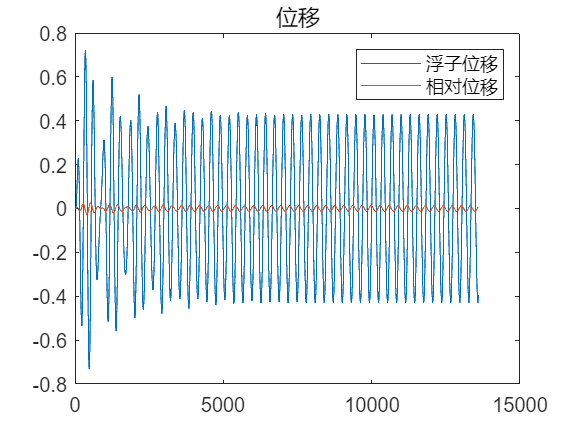

%initialize parameter
g=9.8;                                   %重力加速度 (m/s2)
%l0=0.5;                                 %弹簧原长 (m)       
dt=0.2;                                  %步长设为0.2s
%T_end=40*T;                             %总数值模拟时间(s) 
T_end=200;                               %总数值模拟时间(s)  
%%初值设置               
v1=0;                                    %浮子的初始速度 (m/s)
v2=0;                                    %振子的初始速度 (m/s)
x_f=0;                                   %浮子的初始位移 (m) (以浮子的重心为坐标轴原点)
x_v=0;                                   %振子的初始位移 (m)
X0=[x_f;x_v;v1;v2];
tspan=[0,T_end];
options = odeset('MaxStep', 0.2);  % 设置最大步长为 0.2
[~, X] = ode45(@S_diff_equ, tspan, X0, options);
X=X';
plot(X(1,:))
title('位移')
hold on 
x=X(1,:)-X(2,:);
plot(x)
legend('浮子位移','相对位移')
hold off

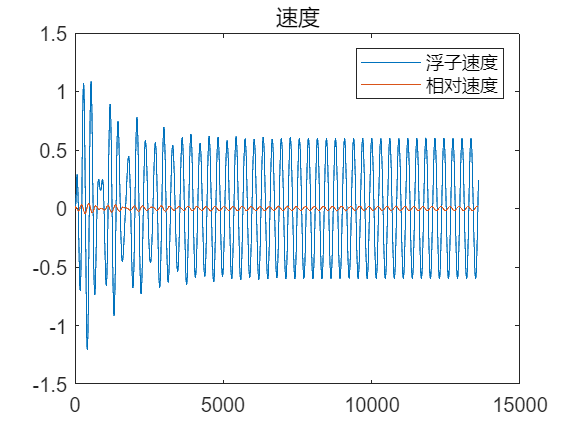

plot(X(3,:))
title('速度')
hold on
plot(X(3,:)-X(4,:))
legend('浮子速度','相对速度')
hold off

t=0:size(X,2)-1;
t=t*0.2;
t=t';
X=X';
X(:,[2,3])=X(:,[3,2]);
X=[t,X];
filename = 'result1-1.xlsx';
data_table = array2table(X);
data = [1, 2, 3; 4, 5, 6; 7, 8, 9];
sheet = 'Sheet1'; % 指定要写入的Sheet名称
xlRange = 'A3';   % 指定写入范围的起始单元格
writetable(data_table, filename, 'Sheet', sheet, 'Range', xlRange);

fprintf('时间 (s)\t浮子\t\t  振子 \n\t\t位移 \t速度 \t  位移 \t     速度 ')

时间 (s)	浮子		  振子 
		位移 	速度 	  位移 	     速度 

disp(X(51,:))

   10.0000    0.0409    0.2200    0.0364    0.2111



disp(X(101,:))

   20.0000    0.2172    0.1230    0.2168    0.1410



disp(X(201,:))

   40.0000   -0.4299   -0.5084   -0.4245   -0.5351



disp(X(301,:))

   60.0000    0.2843    1.0272    0.2673    1.0525



disp(X(501,:))

  100.0000   -0.6394    0.5715   -0.6605    0.5478



function delta_f=ca_f_float(rho,g,x,V0,V_max,r_cost,h)
    %计算浮力   
    if x<=-h
        delta_V=V0-V_max;
    elseif x<=3-h&&x>-h
        delta_V=-x*h*pi*r_cost^2; 
    elseif x<=3.8-h&&x>3-h
        delta_V=-pi*r_cost^2*(3-h)-1/3*pi*((3.8-x)/0.8)^2*(3.8-x);
    else 
        delta_V=-V0;
    end
    delta_f=rho*g*delta_V;
end
function dxdt=S_diff_equ(t,X)
    k=1e+5;
    %initialize parameter
    m1=4866;                                 %浮子质量 (kg)
    r_f=1;                                   %浮子底半径 (m)
    h_cast=3;                                %浮子圆柱部分高度 (m)
    h_cone=0.8;                              %浮子圆锥部分高度 (m)
    V_cast=pi*r_f^2*h_cast;                  %圆柱体积 (m3)
    V_cone=1/3*h_cone*pi*r_f^2;              %圆锥体积(m3)
    V_max=V_cone+V_cast;                     %浮子体积
    m2=2433;                                 %振子质量 (kg)
    m_add=1335.535;                          %垂荡附加质量 (kg)
    g=9.8;                                   %重力加速度 (m/s2)
    G1=m1*g;                                 %浮子重力  (N)
    G2=m2*g;                                 %振子重力  (N)
    rho=1025;                                %海水的密度 (kg/m3)
    ke=80000;                                %弹簧刚度 (N/m)
    w=1.4005;                                %入射波浪频率 (rad/s)orsay %入射波浪角速度（rad/s）                 
    kr=656.3616;                             %垂荡兴波阻尼系数 (N·s/m)
    f_max=6250;                              %垂荡激励力振幅 (N)
    V0=V_max-(G1+G2-f_max)/(rho*g);          %初始沉入水中体积(m3)
    r_cost=1;                                %浮子底半径 (m)
    h=(V_max-(m1*g+m2*g)/(rho*g))/pi;        %水面的高度(m)
    dxdt=zeros(4,1);
    dxdt(1)=X(3);
    dxdt(2)=X(4);
    dxdt(3)=(-k*(X(3)-X(4))-ke*(X(1)-X(2))+f_max*cos(w*t)-kr*X(3)+ca_f_float(rho,g,X(1),V0,V_max,r_cost,h))/(m1+m_add);
    dxdt(4)=(k*(X(3)-X(4))+ke*(X(1)-X(2)))/m2;
    
end